close all
clear

q = 5; % quantization level
% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 3; %the ratio amax/xmax

xmax = 1;
xmax = floor(xmax*q)/q; % We need to make sure they are integers
M = 2*xmax*q+1; % total amount of x samples
x_grid = linspace(-xmax,xmax,M);

% We assign a distribution to X\in x_grid

% x_P = ones(1,M)/M; % Uniform distribution

% x_P = x_grid.^2;
% x_P = x_P./ sum(x_P);

x_P = x_grid-min(x_grid);
x_P = x_P./sum(x_P);

% figure
% plot(x_grid,x_P,'o',LineWidth=1.5);
% xlabel("x",FontSize=13);
% ylabel("P(x)",FontSize=13);
% grid on

% [totalVariance,pMatrix] = opt_variance(eps,r,axRatio,x_grid,x_P);

% For testing, we sample a sequence of epsilon values
eps_grid = linspace(0.9,8,20);

% The variance of optimal mechanism
VarOpt = zeros(1,length(eps_grid));
VarOptWorst = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    [totalVariance,pMatrix,a_grid] = opt_variance(eps_grid(i),delta,r,axRatio,x_grid,x_P);
    VarOpt(i) = totalVariance;
    VarOptWorst(i) = max(pMatrix*(a_grid').^2);
end

--------------------------------
eps = 0.900000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.5839   -0.3138   -0.0278    0.0575    0.1592   -0.1110   -0.1698    0.4393   -0.1665    0.1403   -0.0663


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 1.273684, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.3062   -0.0530    0.0139    0.2386    0.2187    0.0555    0.0213   -0.0874   -0.0555   -0.1416   -0.0334


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 1.647368, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.2488    0.0273   -0.0486    0.3639   -0.0882    0.0555    0.0261    0.0330   -0.0486   -0.0101    0.1533


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 2.021053, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.1566   -0.0151   -0.0659    0.2198   -0.0123         0   -0.0665    0.0102    0.1505    0.0287    0.0157


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 2.394737, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0708   -0.0228    0.0121    0.0407    0.0091         0   -0.1627   -0.1819   -0.0285    0.1390    0.0473


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 2.768421, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.6000   -0.1953    0.6418   -0.0672   -0.4940         0   -0.1870   -0.3653    0.1844    0.0305   -0.2687


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 3.142105, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.2438    0.0055   -0.1015    0.0204    0.0075   -0.0416    0.0152    0.0203    0.0344   -0.1112   -0.0115


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 3.515789, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.6860   -0.0557    0.0954    0.2515   -0.2726         0   -0.1109    0.2346    0.3672   -0.2306   -0.1835


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 3.889474, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0268    0.0086   -0.0104    0.2320   -0.0022   -0.0139    0.0044   -0.0834   -0.0695    0.0153   -0.0409


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 4.263158, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0625    0.0059    0.1288    0.0213   -0.0150    0.0278   -0.0089    0.0500    0.0018    0.0246   -0.0134


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 4.636842, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.0657   -0.1586    0.9617    0.2052   -0.1712    0.1388    0.0272    0.0532    0.3726    0.8130   -0.0534


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 5.010526, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.4522   -0.5812   -0.0396   -0.0064    0.1509    0.0694    0.0070   -0.2157   -0.1642    0.3926   -0.4269


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 5.384211, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.1004    0.0497   -0.0024    0.0035    0.0108   -0.0035    0.0002   -0.0004   -0.0419   -0.0196    0.0015


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 5.757895, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.0413   -0.0171    0.0388   -0.0443   -0.0298         0    0.0026    0.0038   -0.6061    0.4076    0.0647


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 6.131579, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.1050    0.1000   -0.0450    0.0180    0.0193   -0.0087   -0.0030   -0.0078   -0.4918   -0.7136    0.0219


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 6.505263, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.1178   -0.0616    0.0352    0.0428    0.0118    0.0173    0.0012    0.0119   -0.2462   -0.3355   -0.0060


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 6.878947, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.1441   -0.0206    0.0129   -0.0226    0.0054   -0.0087   -0.0001    0.0107    0.3369   -0.4294   -0.0512


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 7.252632, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.2395    0.0081    0.0041    0.0028    0.0009   -0.0087    0.0021    0.0075    0.3077   -0.3998    0.0196


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 7.626316, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.0598   -0.0054   -0.0054    0.0005   -0.0002         0    0.0005    0.2915   -0.9657    0.5786   -0.0024


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


--------------------------------
eps = 8.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.0594    0.0053   -0.0009    0.0039    0.0004    0.0022   -0.0013   -0.1859   -0.5978    0.2173   -0.0084


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


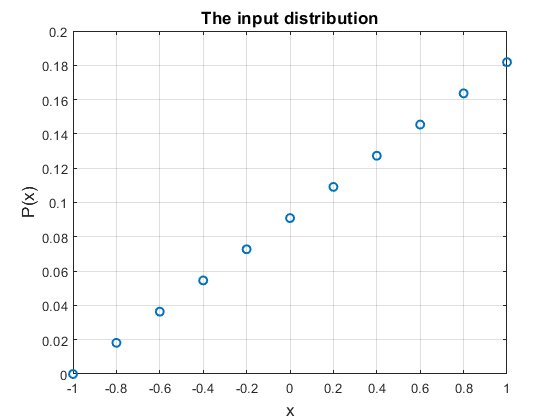

% The variance vector of Laplace mechanism
VarLaplace = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    VarLaplace(i) = 8/(eps_grid(i))^2;
end

% The variance vector of Duchi mechanism
VarDuchi = zeros(1,length(eps_grid));
VarDuchiWorst = zeros(1,length(eps_grid));
var_duchi = @(ti,eps) ((exp(eps)+1)/(exp(eps)-1)).^2-ti.^2;
for i = 1:length(eps_grid)
    temp = var_duchi(x_grid,eps_grid(i));
    VarDuchi(i) = temp *x_P';
    VarDuchiWorst(i) = max(temp);
end


% The variance vector of piece-wise mechanism
VarPiecewise = zeros(1,length(eps_grid));
VarPiecewiseWorst = zeros(1,length(eps_grid));
var_piecewise = @(ti,eps) ti.^2./(exp(eps/2)-1) + (exp(eps/2)+3)/3/(exp(eps/2)-1)^2;
for i = 1:length(eps_grid)
    temp = var_piecewise(x_grid,eps_grid(i));
    VarPiecewise(i) = temp *x_P';
    VarPiecewiseWorst(i) = max(temp);
end

% The variance vector of Hybrid mechanism
VarHybrid = zeros(1,length(eps_grid));
VarHybridWorst = zeros(1,length(eps_grid));
alpha = @(eps) sign(max(eps-0.61,0))*(1-exp(-eps/2));
var_hybrid = @(ti,eps) alpha(eps)*var_piecewise(ti,eps)+(1-alpha(eps))*var_duchi(ti,eps);
for i = 1:length(eps_grid)
    temp = var_hybrid(x_grid,eps_grid(i));
    VarHybrid(i) = temp *x_P';
    VarHybridWorst(i) = max(temp);
end

% The plots

figure
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",FontSize=13)
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on

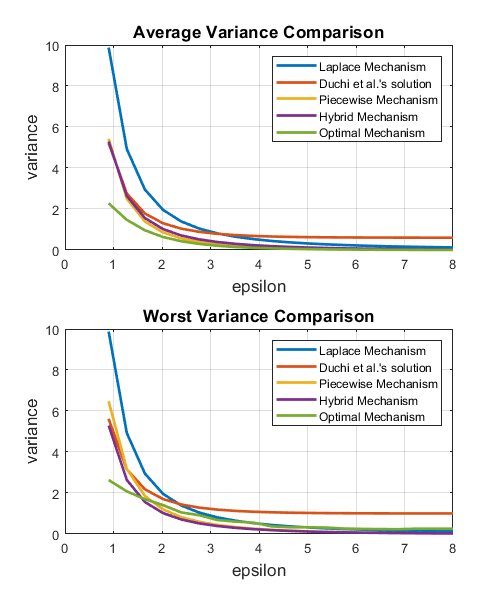


figure;
f = figure;
f.Position = [0 0 500 600];

subplot(2,1,1)
plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchi,LineWidth=2);
hold on
plot(eps_grid,VarPiecewise,LineWidth=2);
hold on
plot(eps_grid,VarHybrid,LineWidth=2);
hold on
plot(eps_grid,VarOpt,LineWidth=2);

title("Average Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on

subplot(2,1,2)
plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchiWorst,LineWidth=2);
hold on
plot(eps_grid,VarPiecewiseWorst,LineWidth=2);
hold on
plot(eps_grid,VarHybridWorst,LineWidth=2);
hold on
plot(eps_grid,VarOptWorst,LineWidth=2);
title("Worst Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on

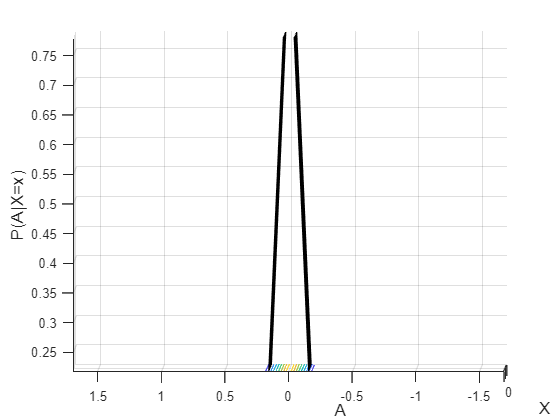

amax = axRatio*max(x_grid); % amax needs to be AT LEAST 2 times larger.
amax = floor(amax*q)/q; % Same as above
N = 2*amax*q+1; % total amount of a samples
a_grid = linspace(-amax,amax,N);

figure
[X_grid,Y_grid] = meshgrid(x_grid,a_grid);
surfc(X_grid,Y_grid,pMatrix');
xlabel("X",FontSize=13);
ylabel("A",FontSize=13);
zlabel("P(A|X=x)",FontSize=13);